% Advanced Whistle Acoustic Synthesis
clear; clc;

% --- 1. PARAMETERS ---
target_freq = 3800;   % Fundamental frequency in Hz
fs = 44100;           % Sampling rate
dur = 4.0;            % Total duration in seconds
t = linspace(0, dur, round(dur * fs)); 

fprintf('Synthesising realistic whistle at %.0f Hz...\n', target_freq);

Synthesising realistic whistle at 3800 Hz...



% --- 2. PITCH PROFILE (Pitch Sag) ---
% A real whistle drops in pitch slightly as breath pressure dies at the end
f_profile = ones(1, length(t)) * target_freq;
release_samples = round(0.25 * fs); % 250ms release tail
sag_amount = 120; % Pitch drops by 120 Hz as breath stops

% Create a downward slope for the last 250ms
f_profile(end-release_samples+1:end) = linspace(target_freq, target_freq - sag_amount, release_samples);

% Integrate the frequency over time to get the continuous phase
phase = cumtrapz(t, f_profile);

% --- 3. HARMONIC SYNTHESIS ---
% Generate the fundamental and the overtones
fund = 1.00 * sin(2 * pi * phase);         % Fundamental (Loudest)
harm2 = 0.15 * sin(2 * pi * 2 * phase);    % 2nd Harmonic (An octave up)
harm3 = 0.05 * sin(2 * pi * 3 * phase);    % 3rd Harmonic 

% --- 4. BREATH NOISE (Chiff) ---
% High-pass filtered noise to simulate turbulent air over the fipple
breath = randn(1, length(t)); 
[b, a] = butter(6, 2000/(fs/2), 'high'); % Cut off low rumble
breath = filter(b, a, breath) * 0.08;    % Scale amplitude to 8%

% Combine raw acoustic elements
raw_audio = fund + harm2 + harm3 + breath;

% --- 5. ADSR ENVELOPE ---
% Shaping the volume over time based on human lung pressure
attack_samp = round(0.06 * fs);   % 60ms ramp up
decay_samp = round(0.10 * fs);    % 100ms drop to sustain level
sustain_samp = length(t) - attack_samp - decay_samp - release_samples;

% Build the curve
env = [linspace(0, 1.0, attack_samp), ...                  % Attack
       linspace(1.0, 0.8, decay_samp), ...                 % Decay
       ones(1, sustain_samp) * 0.8, ...                    % Sustain
       linspace(0.8, 0.0, release_samples)];               % Release

% Apply the envelope to the raw audio
final_audio = raw_audio .* env;

% --- 6. NORMALIZE & PLAY ---
% Prevent digital clipping by bounding the max amplitude to 1.0
final_audio = final_audio / max(abs(final_audio));

disp('Playing advanced synthesis...');

Playing advanced synthesis...


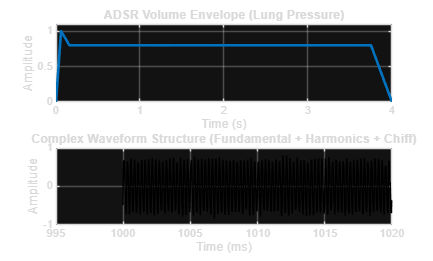

sound(final_audio * 1, fs); % Play at 100% volume

% --- 7. VISUALIZE THE WAVEFORM ---
figure('Name', 'Whistle Synthesis Profile', 'Color', 'w');
subplot(2,1,1);
plot(t, env, 'LineWidth', 2, 'Color', '#0072BD');
title('ADSR Volume Envelope (Lung Pressure)');
xlabel('Time (s)'); ylabel('Amplitude');
grid on; ylim([0 1.1]);

subplot(2,1,2);
% Plot just a 20ms slice of the sustained audio to see the harmonic shape
slice_start = round(1.0 * fs); 
slice_end = slice_start + round(0.02 * fs);
plot(t(slice_start:slice_end)*1000, final_audio(slice_start:slice_end), 'k');
title('Complex Waveform Structure (Fundamental + Harmonics + Chiff)');
xlabel('Time (ms)'); ylabel('Amplitude');
grid on;



filename = 'Custom_Drone_Whistle_3800Hz.wav';
audiowrite(filename, final_audio, fs);

fprintf('\nSuccess! Saved audio file as: %s\n', filename);


Success! Saved audio file as: Custom_Drone_Whistle_3800Hz.wav
